## A: Now, with drive+LDE

### A1. Prepair parameters for drive simulation

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_S = zeros(size(NnS.X),'single');
OD_SMap = zeros(n_S_HC*N_HC,'single');
for NeuInd = 1:length(NnS.X)
    OD_S(NeuInd) = OrientDom(ODNum,NnS.X(NeuInd),NnS.Y(NeuInd),n_S_HC);
    OD_SMap(NnS.Y(NeuInd),NnS.X(NeuInd)) = OD_S(NeuInd);
end

OD_C = zeros(size(NnC.X),'single');
OD_CMap = zeros(n_C_HC*N_HC,'single');
for NeuInd = 1:length(NnC.X)
    OD_C(NeuInd) = OrientDom(ODNum,NnC.X(NeuInd),NnC.Y(NeuInd),n_C_HC);
    OD_CMap(NnC.Y(NeuInd),NnC.X(NeuInd)) = OD_C(NeuInd);
end
OD_E = [OD_S, OD_C];

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
    OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
    OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

StimulusFac = 1;
LGNFreq = 4; % 2 4 10Hz
tMod = 1e3/LGNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = single(tMod*rand(N_E,1));
%PhaseFRS = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Slgn/1e3 * StimulusFac; % 4 to 5

Grating = 22.5; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2,45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;%PhaseFRC = [90 67.5 45 67.5,    0  22.5 45 22.5] *N_Clgn/1e3 * StimulusFac;
PhaseFRC = 45*ones(1,8) *N_Clgn/1e3 * StimulusFac;
lambda_EOn_drive  = [PhaseFRS_Grating(OD_S),PhaseFRC(OD_C)]'; % Should do another for Cplx cells
lambda_EOff_drive = [PhaseFRS_Grating(OD_S+ODNum),PhaseFRC(OD_C+ODNum)]';
% T partition
T = 10000; dt = 0.1; TPar = 10;

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

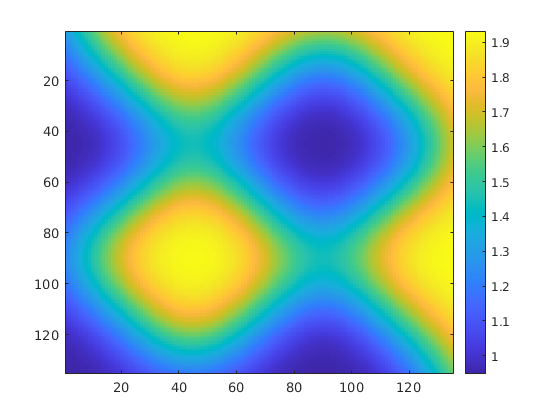

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
lambda_E_drive_Pre = 45 *N_Slgn/1e3 * StimulusFac;
lambda_I_drive_Pre = 45 *N_Ilgn/1e3 * StimulusFac;

% Ver1
% L6Ord_F = [50 33 15 33];
% Ver 4
L6Ord_F = [54 32 10 32];
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
L6C_Drive = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac;
L6I_Drive = L6Ord_F_Grating*NI_L6/1e3 * StimulusFac;

% NOTE: Doing Gaussian blur
FigOn = true;
sig = 0.3;% of HC
L6SFilt = SpatialGaussianFilt(OD_SMap,L6S_Drive,n_S_HC*sig,FigOn);

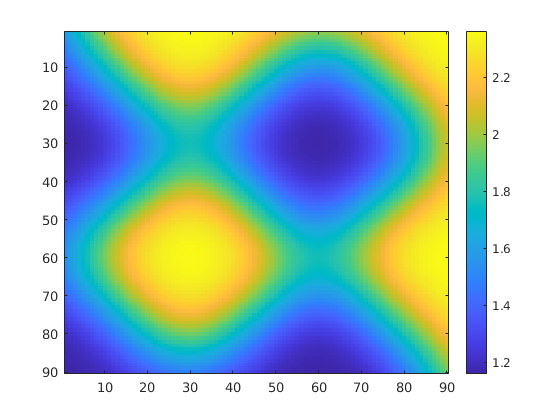

L6CFilt = SpatialGaussianFilt(OD_CMap,L6C_Drive,n_C_HC*sig,FigOn);

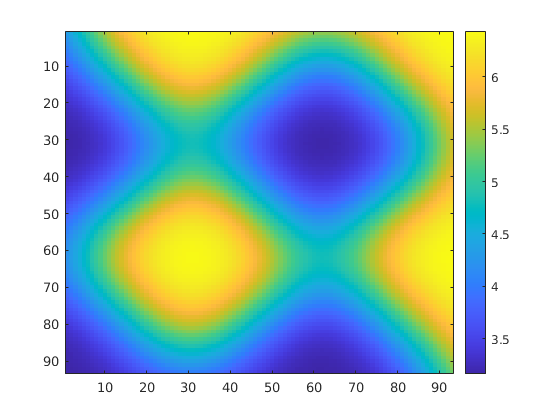

L6IFilt = SpatialGaussianFilt(OD_IMap,L6I_Drive,n_I_HC*sig,FigOn);


rE_L6_Drive = [L6SFilt;L6CFilt];
rI_L6_Drive = L6IFilt;


% Making Poisson here/Reading
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive_Pre*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);

### A2. Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
% SimulationT = 5000;
% E-to-E delay time
T_EEDly = .1; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .1; N_IEDly = floor(T_IEDly/dt); %% NOTE: Was both 0.5
T_EIDly = .1; N_EIDly = floor(T_EIDly/dt);
% The initial states, for more simulation
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
Fields = {'RefTimeE','VE','SpE','GE_ampa_R','GE_nmda_R','GE_gaba_R','GE_ampa_D','GE_nmda_D','GE_gaba_D',...
    'RefTimeI','VI','SpI','GI_ampa_R','GI_nmda_R','GI_gaba_R','GI_ampa_D','GI_nmda_D','GI_gaba_D'};
InSStr = cell2struct(EndState(1:length(Fields)), Fields, 2);
[InEs, InIs] = LargeNW_LoadIniState('InSStr', InSStr,N_E, N_I);
RefTimeE = InEs.RefTimeE; VE = InEs.VE; SpE = InEs.SpE; GE_ampa_R = InEs.GE_ampa_R; GE_nmda_R = InEs.GE_nmda_R; GE_gaba_R = InEs.GE_gaba_R;
GE_ampa_D = InEs.GE_ampa_D; GE_nmda_D = InEs.GE_nmda_D; GE_gaba_D = InEs.GE_gaba_D;
RefTimeI = InIs.RefTimeI; VI = InIs.VI; SpI = InIs.SpI; GI_ampa_R = InIs.GI_ampa_R; GI_nmda_R = InIs.GI_nmda_R; GI_gaba_R = InIs.GI_gaba_R;
GI_ampa_D = InIs.GI_ampa_D; GI_nmda_D = InIs.GI_nmda_D; GI_gaba_D = InIs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);
IEDlyRcd = ones(N_I,N_IEDly);
EIDlyRcd = ones(N_E,N_EIDly);
% if N_EEDly>=size(EndState{19},2)
% EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))];
% else
%     EEDlyRcd = EndState{19}(:,1:N_EEDly);
% end
% if N_IEDly>=size(EndState{20},2)
% IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))];
% else
%     IEDlyRcd = EndState{20}(:,1:N_IEDly);
% end

% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
% SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
    'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
    'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
    'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

Bug here: Though I defined AdjlgnE for every step, it is used only every 100ms...

So: 250on/250off are mixed here...

for TSec = 1:TPar
    tic
    for TimeN = 1:floor(T/dt/TPar)
        % Zero: Use Phase vec to determine different lgn phases for E neurons
        PhaseE = mod(PhaseE + dt,tMod);
        % First, Get input matrices from series
        InpWin = 100; FrameNum = floor(InpWin/dt);
        FrameInd = mod(TimeN, FrameNum);
        if FrameInd == 0
            FrameInd = FrameNum;
        end
        RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
        if FrameInd  == 1 % if the first frame, recompute input mats
            tt = 0:dt:InpWin-dt;
            AdjlgnE = PhaseFRS_Grating(floor(mod(PhaseE + tt, tMod)/MaxOnPhase)*ODNum + OD_E');
            AdjlgnE(EcplxInd,:) = PhaseFRC(floor(mod(PhaseE(EcplxInd) + tt, tMod)/MaxOnPhase)*ODNum + OD_E(EcplxInd)');
            EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE/lambda_E_drive_Pre + AdjlgnE*dt*LGNCurInp)...
                + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
            IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive_Pre*dt*LGNCurInp) ...
                + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa

            EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); %
            InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));

        end


        %      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
        %      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
        %      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
        [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
            oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
            oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
            oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
            oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
            V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
            GE_ampa_D,GE_nmda_D,GE_gaba_D,...
            RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
            GI_ampa_D,GI_nmda_D,GI_gaba_D,...
            EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
            C_EE_Fix_Bd,C_EI_Fix_Bd,C_IE_Fix_Bd,C_II_Fix_Bd,...
            S_EE,S_EI,S_IE,S_II,...
            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
            dt,p_EEFail,...
            gL_E,Ve,rhoE_ampa,rhoE_nmda,...
            gL_I,Vi,rhoI_ampa,rhoI_nmda,...
            EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
            EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
        % iteration
        RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
        GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
        RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
        GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
        EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;

        % Record Every Time time window
        RecordNum = floor(sampleT/dt);
        RecordInd = mod(TimeN, RecordNum);
        SampleRate = 0.1; % Can't be too small for multiple phases
        if RecordInd == 1
            clear E_Sp I_Sp mVETemp mVITemp
            E_Sp = [];
            I_Sp = [];
            mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GE_ETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GE_ITemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
            GI_ETemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            GI_ITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
            mVRecordInd = 1;
        elseif RecordInd == 0
            NWTrace(SampleInd).mVEs = mVETemp;
            NWTrace(SampleInd).mVIs = mVITemp;

            NWTrace(SampleInd).SpEs = E_Sp;
            NWTrace(SampleInd).SpIs = I_Sp;

            NWTrace(SampleInd).GE_I = GE_ITemp;
            NWTrace(SampleInd).GE_E = GE_ETemp;
            NWTrace(SampleInd).GI_I = GI_ITemp;
            NWTrace(SampleInd).GI_E = GI_ETemp;
            SampleInd = SampleInd + 1
            %sum(isnan(oVE))/N_E
            FrESNow = sum(ismember(E_Sp(:,1), find(~EcplxInd)))/N_S/sampleT*1000
            FrECNow = sum(ismember(E_Sp(:,1), find(EcplxInd)))/N_C/sampleT*1000
            FrINow = size(I_Sp,1)/N_I/sampleT*1000
            toc
        end
        E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
        I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);

        if mod(TimeN,floor(1/SampleRate)) == 5
            mVETemp(:,mVRecordInd) = oVE;
            mVITemp(:,mVRecordInd) = oVI;
            % Precompute GE GI
            GE_I = 1/(tau_gaba_D-tau_gaba_R) * (GE_gaba_D - GE_gaba_R); % S_EI is included in amplitude of GE_gaba
            GE_E = 1/(tau_ampa_D-tau_ampa_R) * (GE_ampa_D - GE_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GE_nmda_D - GE_nmda_R); %

            GI_I = 1/(tau_gaba_D-tau_gaba_R) * (GI_gaba_D - GI_gaba_R); % S_EI is included in amplitude of GE_gaba
            GI_E = 1/(tau_ampa_D-tau_ampa_R) * (GI_ampa_D - GI_ampa_R) + ...
                1/(tau_nmda_D-tau_nmda_R) * (GI_nmda_D - GI_nmda_R); %
            GE_ITemp(:,mVRecordInd) = GE_I;
            GE_ETemp(:,mVRecordInd) = GE_E;
            GI_ITemp(:,mVRecordInd) = GI_I;
            GI_ETemp(:,mVRecordInd) = GI_E;
            %record loop goes forward
            mVRecordInd = mVRecordInd + 1;
        end

        if sum(isnan(oVE))>0.80*N_E
            BlowUp = true;
            disp('warning!: Network exploded')
            break
        end

        % the end of iteration
    end
    toc
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz_Deg%.1f_',LGNFreq,Grating) ...
            num2str(TSec) 's.mat'];
    EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
        RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
        EEDlyRcd, IEDlyRcd};
    save([SaveFolder text],'NWTrace','EndState','PhaseE','-v7.3')

    clear NWTrace
    NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
        'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1),...
        'GE_E',   cell(WinNum,1), 'GE_I',   cell(WinNum,1),...
        'GI_E',   cell(WinNum,1), 'GI_I',   cell(WinNum,1));
end

SampleInd = 2

FrESNow = 8.3720

FrECNow = 16.1407

FrINow = 45.9151

Elapsed time is 2.118427 seconds.


SampleInd = 3

FrESNow = 8.8439

FrECNow = 20.2346

FrINow = 48.7825

Elapsed time is 3.457441 seconds.


SampleInd = 4

FrESNow = 8.9141

FrECNow = 26.8444

FrINow = 54.0872

Elapsed time is 5.616990 seconds.


SampleInd = 5

FrESNow = 8.6365

FrECNow = 26.0099

FrINow = 53.2316

Elapsed time is 7.009724 seconds.


SampleInd = 6

FrESNow = 9.0348

FrECNow = 30.0395

FrINow = 56.8482

Elapsed time is 9.133995 seconds.


SampleInd = 7

FrESNow = 8.2491

FrECNow = 24.2568

FrINow = 52.3621

Elapsed time is 10.497401 seconds.


SampleInd = 8

FrESNow = 8.6694

FrECNow = 26.9827

FrINow = 54.7901

Elapsed time is 12.591585 seconds.


SampleInd = 9

FrESNow = 8.2919

FrECNow = 24.2593

FrINow = 52.0523

Elapsed time is 13.971772 seconds.


SampleInd = 10

FrESNow = 9.0272

FrECNow = 29.8889

FrINow = 57.2136

Elapsed time is 16.122469 seconds.


SampleInd = 11

FrESNow = 8.0362

FrECNow = 24.0642

FrINow = 51.8164

Elapsed time is 17.469817 seconds.


SampleInd = 12

FrESNow = 8.7781

FrECNow = 25.8321

FrINow = 54.1334

Elapsed time is 19.513540 seconds.


SampleInd = 13

FrESNow = 8.3501

FrECNow = 28.4272

FrINow = 55.2503

Elapsed time is 20.902177 seconds.


SampleInd = 14

FrESNow = 8.6080

FrECNow = 28.7654

FrINow = 56.0620

Elapsed time is 22.957875 seconds.


SampleInd = 15

FrESNow = 8.7726

FrECNow = 28.9951

FrINow = 55.9695

Elapsed time is 24.350001 seconds.


SampleInd = 16

FrESNow = 8.7517

FrECNow = 25.6099

FrINow = 54.5057

Elapsed time is 26.405602 seconds.


SampleInd = 17

FrESNow = 8.2359

FrECNow = 23.1704

FrINow = 51.2267

Elapsed time is 27.738932 seconds.


SampleInd = 18

FrESNow = 8.8757

FrECNow = 30.7975

FrINow = 57.2089

Elapsed time is 29.936926 seconds.


SampleInd = 19

FrESNow = 8.7177

FrECNow = 29.3160

FrINow = 56.8413

Elapsed time is 31.390334 seconds.


SampleInd = 20

FrESNow = 8.7089

FrECNow = 26.3037

FrINow = 54.5520

Elapsed time is 33.449432 seconds.


SampleInd = 21

FrESNow = 8.2590

FrECNow = 23.9309

FrINow = 52.3274

Elapsed time is 34.766047 seconds.


Elapsed time is 34.766885 seconds.


SampleInd = 22

FrESNow = 8.7254

FrECNow = 28.0148

FrINow = 55.1671

Elapsed time is 2.048244 seconds.


SampleInd = 23

FrESNow = 8.5586

FrECNow = 25.4000

FrINow = 53.3634

Elapsed time is 3.425110 seconds.


SampleInd = 24

FrESNow = 8.3446

FrECNow = 24.3407

FrINow = 52.1609

Elapsed time is 5.516075 seconds.


SampleInd = 25

FrESNow = 8.7440

FrECNow = 31.3086

FrINow = 57.8980

Elapsed time is 6.977669 seconds.


SampleInd = 26

FrESNow = 9.1643

FrECNow = 33.7877

FrINow = 60.2844

Elapsed time is 9.170010 seconds.


SampleInd = 27

FrESNow = 7.8508

FrECNow = 21.8321

FrINow = 50.5561

Elapsed time is 10.473451 seconds.


SampleInd = 28

FrESNow = 8.4609

FrECNow = 23.5185

FrINow = 52.2951

Elapsed time is 12.468851 seconds.


SampleInd = 29

FrESNow = 8.7407

FrECNow = 28.5531

FrINow = 55.6111

Elapsed time is 13.888146 seconds.


SampleInd = 30

FrESNow = 8.4565

FrECNow = 27.3457

FrINow = 54.5658

Elapsed time is 15.925544 seconds.


SampleInd = 31

FrESNow = 8.1964

FrECNow = 23.5062

FrINow = 51.7493

Elapsed time is 17.311181 seconds.


SampleInd = 32

FrESNow = 8.8900

FrECNow = 30.1926

FrINow = 56.8320

Elapsed time is 19.449904 seconds.


SampleInd = 33

FrESNow = 8.5202

FrECNow = 27.2420

FrINow = 54.8826

Elapsed time is 20.915987 seconds.


SampleInd = 34

FrESNow = 8.5816

FrECNow = 26.0123

FrINow = 54.1889

Elapsed time is 22.963928 seconds.


SampleInd = 35

FrESNow = 8.3830

FrECNow = 25.1852

FrINow = 52.8801

Elapsed time is 24.315564 seconds.


SampleInd = 36

FrESNow = 8.4916

FrECNow = 26.9062

FrINow = 54.3462

Elapsed time is 26.354980 seconds.


SampleInd = 37

FrESNow = 9.0623

FrECNow = 31.8568

FrINow = 58.3004

Elapsed time is 27.858936 seconds.


SampleInd = 38

FrESNow = 8.5739

FrECNow = 25.7284

FrINow = 53.7843

Elapsed time is 29.923389 seconds.


SampleInd = 39

FrESNow = 8.5564

FrECNow = 26.8642

FrINow = 54.9751

Elapsed time is 31.410669 seconds.


SampleInd = 40

FrESNow = 8.5300

FrECNow = 27.9630

FrINow = 55.0931

Elapsed time is 33.492363 seconds.


SampleInd = 41

FrESNow = 8.3819

FrECNow = 24.4420

FrINow = 52.4616

Elapsed time is 34.849092 seconds.


Elapsed time is 34.849858 seconds.


SampleInd = 42

FrESNow = 8.7276

FrECNow = 28.3704

FrINow = 55.7845

Elapsed time is 2.080536 seconds.


SampleInd = 43

FrESNow = 8.5202

FrECNow = 26.5580

FrINow = 54.3647

Elapsed time is 3.472269 seconds.


SampleInd = 44

FrESNow = 9.1391

FrECNow = 30.5679

FrINow = 57.7269

Elapsed time is 5.592693 seconds.


SampleInd = 45

FrESNow = 8.3369

FrECNow = 24.3185

FrINow = 52.7945

Elapsed time is 7.003058 seconds.


SampleInd = 46

FrESNow = 8.5772

FrECNow = 25.7432

FrINow = 53.6363

Elapsed time is 9.114384 seconds.


SampleInd = 47

FrESNow = 8.5937

FrECNow = 27.3284

FrINow = 54.9127

Elapsed time is 10.555814 seconds.


SampleInd = 48

FrESNow = 8.2151

FrECNow = 24.2370

FrINow = 52.2072

Elapsed time is 12.560668 seconds.


SampleInd = 49

FrESNow = 8.7484

FrECNow = 33.2642

FrINow = 59.0542

Elapsed time is 14.006526 seconds.


SampleInd = 50

FrESNow = 8.6793

FrECNow = 30.0099

FrINow = 57.5396

Elapsed time is 16.089668 seconds.


SampleInd = 51

FrESNow = 8.2008

FrECNow = 23.3778

FrINow = 51.8603

Elapsed time is 17.412528 seconds.


SampleInd = 52

FrESNow = 8.6178

FrECNow = 28.9333

FrINow = 56.0319

Elapsed time is 19.522410 seconds.


SampleInd = 53

FrESNow = 8.2348

FrECNow = 22.6198

FrINow = 51.3794

Elapsed time is 20.930571 seconds.


SampleInd = 54

FrESNow = 9.1160

FrECNow = 32.3012

FrINow = 58.5455

Elapsed time is 23.119706 seconds.


SampleInd = 55

FrESNow = 8.6134

FrECNow = 26.8321

FrINow = 54.8503

Elapsed time is 24.555964 seconds.


SampleInd = 56

FrESNow = 8.1053

FrECNow = 23.6321

FrINow = 51.8580

Elapsed time is 26.588505 seconds.


SampleInd = 57

FrESNow = 8.3610

FrECNow = 24.5259

FrINow = 52.6072

Elapsed time is 27.961963 seconds.


SampleInd = 58

FrESNow = 8.7550

FrECNow = 28.8025

FrINow = 56.1429

Elapsed time is 30.108246 seconds.


SampleInd = 59

FrESNow = 9.1139

FrECNow = 31.2148

FrINow = 58.1085

Elapsed time is 31.551199 seconds.


SampleInd = 60

FrESNow = 8.2798

FrECNow = 23.1654

FrINow = 51.7008

Elapsed time is 33.564134 seconds.


SampleInd = 61

FrESNow = 8.6529

FrECNow = 25.0296

FrINow = 53.3102

Elapsed time is 34.942102 seconds.


Elapsed time is 34.942878 seconds.


SampleInd = 62

FrESNow = 8.9888

FrECNow = 31.0346

FrINow = 57.7824

Elapsed time is 2.087008 seconds.


SampleInd = 63

FrESNow = 8.3435

FrECNow = 26.4617

FrINow = 54.2953

Elapsed time is 3.449308 seconds.


SampleInd = 64

FrESNow = 8.2480

FrECNow = 22.7136

FrINow = 51.3516

Elapsed time is 5.429306 seconds.


SampleInd = 65

FrESNow = 8.8516

FrECNow = 31.2321

FrINow = 57.7061

Elapsed time is 6.887245 seconds.


SampleInd = 66

FrESNow = 8.2831

FrECNow = 23.8099

FrINow = 52.3691

Elapsed time is 8.921689 seconds.


SampleInd = 67

FrESNow = 8.5915

FrECNow = 28.6444

FrINow = 55.7475

Elapsed time is 10.313897 seconds.


SampleInd = 68

FrESNow = 8.8307

FrECNow = 31.1358

FrINow = 57.3824

Elapsed time is 12.459548 seconds.


SampleInd = 69

FrESNow = 8.6562

FrECNow = 26.7901

FrINow = 55.1139

Elapsed time is 13.869712 seconds.


SampleInd = 70

FrESNow = 8.2546

FrECNow = 22.4914

FrINow = 50.9585

Elapsed time is 15.918607 seconds.


SampleInd = 71

FrESNow = 8.6321

FrECNow = 29.5407

FrINow = 56.4944

Elapsed time is 17.389313 seconds.


SampleInd = 72

FrESNow = 8.7945

FrECNow = 28.9259

FrINow = 56.0134

Elapsed time is 19.520950 seconds.


SampleInd = 73

FrESNow = 8.6903

FrECNow = 27.3556

FrINow = 54.8248

Elapsed time is 20.956787 seconds.


SampleInd = 74

FrESNow = 8.4741

FrECNow = 27.0370

FrINow = 54.6838

Elapsed time is 23.122885 seconds.


SampleInd = 75

FrESNow = 8.6727

FrECNow = 27.2716

FrINow = 54.9566

Elapsed time is 24.523271 seconds.


SampleInd = 76

FrESNow = 8.6321

FrECNow = 27.4519

FrINow = 55.2850

Elapsed time is 26.696685 seconds.


SampleInd = 77

FrESNow = 8.3621

FrECNow = 25.4444

FrINow = 53.1992

Elapsed time is 28.061840 seconds.


SampleInd = 78

FrESNow = 8.3193

FrECNow = 25.0049

FrINow = 52.8570

Elapsed time is 30.164114 seconds.


SampleInd = 79

FrESNow = 8.5246

FrECNow = 31.4198

FrINow = 57.8818

Elapsed time is 31.716911 seconds.


SampleInd = 80

FrESNow = 8.4587

FrECNow = 24.6049

FrINow = 52.9356

Elapsed time is 33.839381 seconds.


SampleInd = 81

FrESNow = 9.0491

FrECNow = 30.9753

FrINow = 58.2842

Elapsed time is 35.289088 seconds.


Elapsed time is 35.289878 seconds.


SampleInd = 82

FrESNow = 8.3314

FrECNow = 22.2667

FrINow = 50.8521

Elapsed time is 1.997742 seconds.


SampleInd = 83

FrESNow = 8.6310

FrECNow = 26.8642

FrINow = 54.1242

Elapsed time is 3.373980 seconds.


SampleInd = 84

FrESNow = 8.5597

FrECNow = 26.3012

FrINow = 54.0224

Elapsed time is 5.439947 seconds.


SampleInd = 85

FrESNow = 8.9361

FrECNow = 29.6691

FrINow = 56.7811

Elapsed time is 6.859914 seconds.


SampleInd = 86

FrESNow = 8.7693

FrECNow = 25.3778

FrINow = 53.9507

Elapsed time is 8.931571 seconds.


SampleInd = 87

FrESNow = 7.9594

FrECNow = 25.9259

FrINow = 52.9772

Elapsed time is 10.289465 seconds.


SampleInd = 88

FrESNow = 8.3797

FrECNow = 30.1753

FrINow = 56.7071

Elapsed time is 12.403497 seconds.


SampleInd = 89

FrESNow = 8.6848

FrECNow = 26.1235

FrINow = 54.5265

Elapsed time is 13.771030 seconds.


SampleInd = 90

FrESNow = 8.4532

FrECNow = 26.7457

FrINow = 53.9230

Elapsed time is 15.834064 seconds.


SampleInd = 91

FrESNow = 8.7396

FrECNow = 29.9111

FrINow = 56.8528

Elapsed time is 17.306292 seconds.


SampleInd = 92

FrESNow = 8.2809

FrECNow = 23.9580

FrINow = 51.7285

Elapsed time is 19.372249 seconds.


SampleInd = 93

FrESNow = 8.4236

FrECNow = 28.2568

FrINow = 55.2018

Elapsed time is 20.781776 seconds.


SampleInd = 94

FrESNow = 8.7693

FrECNow = 28.4815

FrINow = 55.5625

Elapsed time is 22.873888 seconds.


SampleInd = 95

FrESNow = 8.5948

FrECNow = 25.2000

FrINow = 53.6062

Elapsed time is 24.304130 seconds.


SampleInd = 96

FrESNow = 8.5630

FrECNow = 27.1802

FrINow = 54.7878

Elapsed time is 26.380608 seconds.


SampleInd = 97

FrESNow = 8.4412

FrECNow = 25.7160

FrINow = 53.4790

Elapsed time is 27.737414 seconds.


SampleInd = 98

FrESNow = 8.5937

FrECNow = 28.6963

FrINow = 55.8169

Elapsed time is 29.880692 seconds.


SampleInd = 99

FrESNow = 8.5410

FrECNow = 26.0938

FrINow = 54.0479

Elapsed time is 31.244175 seconds.


SampleInd = 100

FrESNow = 8.5937

FrECNow = 29.9975

FrINow = 56.7696

Elapsed time is 33.349240 seconds.


SampleInd = 101

FrESNow = 8.5037

FrECNow = 27.2074

FrINow = 54.8942

Elapsed time is 34.768787 seconds.


Elapsed time is 34.769698 seconds.


SampleInd = 102

FrESNow = 8.4027

FrECNow = 23.9111

FrINow = 52.2419

Elapsed time is 2.006113 seconds.


SampleInd = 103

FrESNow = 8.2579

FrECNow = 25.9309

FrINow = 53.4513

Elapsed time is 3.367492 seconds.


SampleInd = 104

FrESNow = 8.8362

FrECNow = 32.9605

FrINow = 58.6403

Elapsed time is 5.514472 seconds.


SampleInd = 105

FrESNow = 8.0999

FrECNow = 22.3012

FrINow = 51.1874

Elapsed time is 6.820832 seconds.


SampleInd = 106

FrESNow = 8.6617

FrECNow = 30.8914

FrINow = 57.1835

Elapsed time is 8.978933 seconds.


SampleInd = 107

FrESNow = 8.6036

FrECNow = 26.1654

FrINow = 54.2537

Elapsed time is 10.368234 seconds.


SampleInd = 108

FrESNow = 8.7791

FrECNow = 29.3877

FrINow = 56.7696

Elapsed time is 12.451042 seconds.


SampleInd = 109

FrESNow = 8.0955

FrECNow = 23.7457

FrINow = 51.5967

Elapsed time is 13.764931 seconds.


SampleInd = 110

FrESNow = 8.4905

FrECNow = 25.8765

FrINow = 53.6848

Elapsed time is 15.849732 seconds.


SampleInd = 111

FrESNow = 8.8977

FrECNow = 27.1531

FrINow = 55.2642

Elapsed time is 17.239923 seconds.


SampleInd = 112

FrESNow = 8.6694

FrECNow = 29.6519

FrINow = 56.4736

Elapsed time is 19.367174 seconds.


SampleInd = 113

FrESNow = 8.4576

FrECNow = 24.1605

FrINow = 52.2766

Elapsed time is 20.716946 seconds.


SampleInd = 114

FrESNow = 8.6145

FrECNow = 30.7012

FrINow = 57.4934

Elapsed time is 22.837619 seconds.


SampleInd = 115

FrESNow = 8.5125

FrECNow = 26.6395

FrINow = 54.3970

Elapsed time is 24.247381 seconds.


SampleInd = 116

FrESNow = 8.5904

FrECNow = 27.4247

FrINow = 54.7647

Elapsed time is 26.357859 seconds.


SampleInd = 117

FrESNow = 8.2875

FrECNow = 25.0988

FrINow = 53.1113

Elapsed time is 27.812027 seconds.


SampleInd = 118

FrESNow = 8.8483

FrECNow = 27.8790

FrINow = 55.3590

Elapsed time is 30.005085 seconds.


SampleInd = 119

FrESNow = 8.2996

FrECNow = 24.2840

FrINow = 52.2349

Elapsed time is 31.422565 seconds.


SampleInd = 120

FrESNow = 9.0502

FrECNow = 31.9284

FrINow = 58.9733

Elapsed time is 33.585438 seconds.


SampleInd = 121

FrESNow = 7.8804

FrECNow = 20.9951

FrINow = 49.6427

Elapsed time is 34.902883 seconds.


Elapsed time is 34.903648 seconds.


SampleInd = 122

FrESNow = 8.6628

FrECNow = 29.2074

FrINow = 55.8030

Elapsed time is 2.122758 seconds.


SampleInd = 123

FrESNow = 8.9229

FrECNow = 28.6988

FrINow = 56.3002

Elapsed time is 3.538574 seconds.


SampleInd = 124

FrESNow = 8.3281

FrECNow = 24.5802

FrINow = 53.0651

Elapsed time is 5.575506 seconds.


SampleInd = 125

FrESNow = 8.4203

FrECNow = 25.0148

FrINow = 53.0605

Elapsed time is 6.927467 seconds.


SampleInd = 126

FrESNow = 8.8044

FrECNow = 29.4395

FrINow = 56.6031

Elapsed time is 9.024276 seconds.


SampleInd = 127

FrESNow = 8.4752

FrECNow = 27.4370

FrINow = 54.3693

Elapsed time is 10.457427 seconds.


SampleInd = 128

FrESNow = 8.6102

FrECNow = 29.9580

FrINow = 56.6933

Elapsed time is 12.624350 seconds.


SampleInd = 129

FrESNow = 8.5289

FrECNow = 27.5506

FrINow = 55.3752

Elapsed time is 14.064386 seconds.


SampleInd = 130

FrESNow = 8.3819

FrECNow = 24.7926

FrINow = 52.8940

Elapsed time is 16.209041 seconds.


SampleInd = 131

FrESNow = 8.6299

FrECNow = 28.4914

FrINow = 55.2896

Elapsed time is 17.665954 seconds.


SampleInd = 132

FrESNow = 8.5158

FrECNow = 26.2247

FrINow = 53.9068

Elapsed time is 19.948880 seconds.


SampleInd = 133

FrESNow = 8.5674

FrECNow = 25.9136

FrINow = 53.7796

Elapsed time is 21.427389 seconds.


SampleInd = 134

FrESNow = 8.4477

FrECNow = 26.1654

FrINow = 53.9831

Elapsed time is 23.637152 seconds.


SampleInd = 135

FrESNow = 8.9064

FrECNow = 28.4494

FrINow = 55.7290

Elapsed time is 25.079962 seconds.


SampleInd = 136

FrESNow = 8.5410

FrECNow = 28.4000

FrINow = 55.4076

Elapsed time is 27.232175 seconds.


SampleInd = 137

FrESNow = 8.2096

FrECNow = 24.5235

FrINow = 52.4176

Elapsed time is 28.609020 seconds.


SampleInd = 138

FrESNow = 8.6310

FrECNow = 28.1457

FrINow = 55.5232

Elapsed time is 30.814944 seconds.


SampleInd = 139

FrESNow = 8.7111

FrECNow = 27.1407

FrINow = 54.7393

Elapsed time is 32.255201 seconds.


SampleInd = 140

FrESNow = 8.5147

FrECNow = 25.1704

FrINow = 53.2108

Elapsed time is 34.379070 seconds.


SampleInd = 141

FrESNow = 8.4082

FrECNow = 26.0370

FrINow = 53.7426

Elapsed time is 35.774072 seconds.


Elapsed time is 35.774867 seconds.


SampleInd = 142

FrESNow = 8.5816

FrECNow = 27.9012

FrINow = 55.2434

Elapsed time is 2.129242 seconds.


SampleInd = 143

FrESNow = 8.4093

FrECNow = 22.5877

FrINow = 51.3100

Elapsed time is 3.461967 seconds.


SampleInd = 144

FrESNow = 8.8922

FrECNow = 29.2716

FrINow = 56.5638

Elapsed time is 5.692500 seconds.


SampleInd = 145

FrESNow = 8.7923

FrECNow = 27.1210

FrINow = 54.7832

Elapsed time is 7.196263 seconds.


SampleInd = 146

FrESNow = 8.4598

FrECNow = 28.2099

FrINow = 55.6319

Elapsed time is 9.387221 seconds.


SampleInd = 147

FrESNow = 8.8121

FrECNow = 27.6173

FrINow = 55.4399

Elapsed time is 10.854029 seconds.


SampleInd = 148

FrESNow = 8.5652

FrECNow = 27.2889

FrINow = 54.8688

Elapsed time is 12.972747 seconds.


SampleInd = 149

FrESNow = 8.7276

FrECNow = 30.0642

FrINow = 56.6909

Elapsed time is 14.458978 seconds.


SampleInd = 150

FrESNow = 8.3160

FrECNow = 25.0914

FrINow = 53.5021

Elapsed time is 16.534418 seconds.


SampleInd = 151

FrESNow = 8.6705

FrECNow = 27.7679

FrINow = 54.7069

Elapsed time is 18.009523 seconds.


SampleInd = 152

FrESNow = 8.8044

FrECNow = 29.0741

FrINow = 56.2978

Elapsed time is 20.163192 seconds.


SampleInd = 153

FrESNow = 8.3171

FrECNow = 24.6049

FrINow = 52.7529

Elapsed time is 21.538226 seconds.


SampleInd = 154

FrESNow = 9.2433

FrECNow = 34.2889

FrINow = 61.0868

Elapsed time is 23.784465 seconds.


SampleInd = 155

FrESNow = 8.0395

FrECNow = 20.9037

FrINow = 49.6104

Elapsed time is 25.170264 seconds.


SampleInd = 156

FrESNow = 8.4466

FrECNow = 24.6963

FrINow = 52.5795

Elapsed time is 27.273387 seconds.


SampleInd = 157

FrESNow = 8.8132

FrECNow = 30.9432

FrINow = 57.3361

Elapsed time is 28.832043 seconds.


SampleInd = 158

FrESNow = 8.5849

FrECNow = 26.0593

FrINow = 54.3832

Elapsed time is 30.983016 seconds.


SampleInd = 159

FrESNow = 8.2370

FrECNow = 27.3383

FrINow = 54.5358

Elapsed time is 32.469716 seconds.


SampleInd = 160

FrESNow = 8.6398

FrECNow = 25.1259

FrINow = 53.3611

Elapsed time is 34.551467 seconds.


SampleInd = 161

FrESNow = 8.8472

FrECNow = 28.5160

FrINow = 55.7914

Elapsed time is 35.997930 seconds.


Elapsed time is 35.998747 seconds.


SampleInd = 162

FrESNow = 8.8439

FrECNow = 28.4198

FrINow = 56.2793

Elapsed time is 2.097114 seconds.


SampleInd = 163

FrESNow = 8.3226

FrECNow = 24.5951

FrINow = 52.4523

Elapsed time is 3.460853 seconds.


SampleInd = 164

FrESNow = 8.3940

FrECNow = 25.7012

FrINow = 53.4790

Elapsed time is 5.638020 seconds.


SampleInd = 165

FrESNow = 8.8812

FrECNow = 27.9679

FrINow = 55.9417

Elapsed time is 7.051369 seconds.


SampleInd = 166

FrESNow = 8.2118

FrECNow = 25.0914

FrINow = 52.4731

Elapsed time is 9.173628 seconds.


SampleInd = 167

FrESNow = 8.8461

FrECNow = 32.4593

FrINow = 58.5016

Elapsed time is 10.648341 seconds.


SampleInd = 168

FrESNow = 8.3325

FrECNow = 26.5259

FrINow = 54.4641

Elapsed time is 12.797952 seconds.


SampleInd = 169

FrESNow = 8.6771

FrECNow = 27.9259

FrINow = 55.4584

Elapsed time is 14.232024 seconds.


SampleInd = 170

FrESNow = 8.5959

FrECNow = 28.5926

FrINow = 56.3788

Elapsed time is 16.443946 seconds.


SampleInd = 171

FrESNow = 8.2546

FrECNow = 25.9383

FrINow = 53.7264

Elapsed time is 17.880412 seconds.


SampleInd = 172

FrESNow = 8.4763

FrECNow = 26.8938

FrINow = 54.3045

Elapsed time is 20.132322 seconds.


SampleInd = 173

FrESNow = 8.4818

FrECNow = 23.9210

FrINow = 52.0384

Elapsed time is 21.521764 seconds.


SampleInd = 174

FrESNow = 9.1951

FrECNow = 31.4123

FrINow = 58.4669

Elapsed time is 23.751389 seconds.


SampleInd = 175

FrESNow = 8.4060

FrECNow = 27.6099

FrINow = 55.0838

Elapsed time is 25.148160 seconds.


SampleInd = 176

FrESNow = 9.1764

FrECNow = 33.1951

FrINow = 60.3330

Elapsed time is 27.417134 seconds.


SampleInd = 177

FrESNow = 7.6543

FrECNow = 20.0667

FrINow = 48.7733

Elapsed time is 28.712492 seconds.


SampleInd = 178

FrESNow = 8.6562

FrECNow = 28.3877

FrINow = 55.6550

Elapsed time is 30.897655 seconds.


SampleInd = 179

FrESNow = 8.4708

FrECNow = 24.9259

FrINow = 52.8940

Elapsed time is 32.310486 seconds.


SampleInd = 180

FrESNow = 8.7133

FrECNow = 30.7333

FrINow = 57.2205

Elapsed time is 34.455618 seconds.


SampleInd = 181

FrESNow = 8.5224

FrECNow = 26.7160

FrINow = 54.3439

Elapsed time is 35.826493 seconds.


Elapsed time is 35.827291 seconds.


SampleInd = 182

FrESNow = 8.2019

FrECNow = 24.4543

FrINow = 52.5564

Elapsed time is 2.039735 seconds.


SampleInd = 183

FrESNow = 8.8593

FrECNow = 29.2395

FrINow = 56.4551

Elapsed time is 3.453325 seconds.


SampleInd = 184

FrESNow = 8.2645

FrECNow = 25.5728

FrINow = 53.2640

Elapsed time is 5.494774 seconds.


SampleInd = 185

FrESNow = 8.7802

FrECNow = 28.1136

FrINow = 55.5417

Elapsed time is 6.934986 seconds.


SampleInd = 186

FrESNow = 8.1613

FrECNow = 27.2642

FrINow = 54.5150

Elapsed time is 9.007125 seconds.


SampleInd = 187

FrESNow = 8.7528

FrECNow = 27.8025

FrINow = 55.4191

Elapsed time is 10.395893 seconds.


SampleInd = 188

FrESNow = 8.6892

FrECNow = 27.8247

FrINow = 55.4908

Elapsed time is 12.487008 seconds.


SampleInd = 189

FrESNow = 8.4938

FrECNow = 25.6420

FrINow = 53.2825

Elapsed time is 13.844566 seconds.


SampleInd = 190

FrESNow = 8.6979

FrECNow = 29.3086

FrINow = 56.9153

Elapsed time is 15.967673 seconds.


SampleInd = 191

FrESNow = 8.7385

FrECNow = 26.7852

FrINow = 55.1000

Elapsed time is 17.348437 seconds.


SampleInd = 192

FrESNow = 7.9484

FrECNow = 25.0222

FrINow = 52.4107

Elapsed time is 19.464434 seconds.


SampleInd = 193

FrESNow = 8.8198

FrECNow = 27.8321

FrINow = 55.2526

Elapsed time is 20.865687 seconds.


SampleInd = 194

FrESNow = 8.5026

FrECNow = 26.4840

FrINow = 54.3647

Elapsed time is 23.040622 seconds.


SampleInd = 195

FrESNow = 8.5586

FrECNow = 27.6790

FrINow = 55.2041

Elapsed time is 24.467719 seconds.


SampleInd = 196

FrESNow = 8.3424

FrECNow = 25.9111

FrINow = 53.5923

Elapsed time is 26.571436 seconds.


SampleInd = 197

FrESNow = 8.6145

FrECNow = 26.3383

FrINow = 54.1866

Elapsed time is 27.967048 seconds.


SampleInd = 198

FrESNow = 8.8351

FrECNow = 27.3506

FrINow = 54.8826

Elapsed time is 30.092331 seconds.


SampleInd = 199

FrESNow = 8.3742

FrECNow = 25.1309

FrINow = 53.2986

Elapsed time is 31.555639 seconds.


SampleInd = 200

FrESNow = 8.8165

FrECNow = 27.0938

FrINow = 54.7462

Elapsed time is 33.668389 seconds.


SampleInd = 201

FrESNow = 8.7978

FrECNow = 29.0617

FrINow = 56.7048

Elapsed time is 35.148006 seconds.


Elapsed time is 35.148821 seconds.


%save([SaveFolder,'DriveWkSp_SCSepa_Cconst_Conn.mat'],'CMatAll','EcplxInd');

### A3. read data, and get spike and mV

DriveDataFolder = ['/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive/Data/Paper2_NetworkTuning/Fig1V4/' ...
    sprintf('SIEMt%.3f_SEIMt%.3f/',S_IE/S_II,S_EI/S_EE)];
%addpath(DriveDataFolder)
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
GE_E = []; GE_I = [];
GI_E = []; GI_I = [];
PhaseEAll = [];
for TSec = 1:TPar
    %text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz',LGNFreq) num2str(TSec) 's.mat'];
    text = [sprintf('DriveWkSp_SCSepa_Cconst_%dHz_Deg%.1f_',LGNFreq,Grating) ...
            num2str(TSec) 's.mat'];
    load([DriveDataFolder text],'NWTrace');

    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    GE_ECurrent = [];GE_ICurrent = [];
    GI_ECurrent = [];GI_ICurrent = [];
    PhaseECurrent = [];
    for WinInd = 1:length(NWTrace)
        SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
        SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
        mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
        mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];

        %     GE_ECurrent = [GE_ECurrent, NWTrace(WinInd).GE_E];
        %     GE_ICurrent = [GE_ICurrent, NWTrace(WinInd).GE_I];
        %     GI_ECurrent = [GI_ECurrent, NWTrace(WinInd).GI_E];
        %     GI_ICurrent = [GI_ICurrent, NWTrace(WinInd).GI_I];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];

    %     GE_E = [GE_E, GE_ECurrent];
    %     GE_I = [GE_I, GE_ICurrent];
    %     GI_E = [GI_E, GI_ECurrent];
    %     GI_I = [GI_I, GI_ICurrent];

end
load([DriveDataFolder ...
    text],'PhaseE');
load( 'DriveWkSp_SCSepa_Cconst_Conn.mat','CMatAll','EcplxInd');
% Get conn mats
C_EE_Fix_Bd = CMatAll.C_EE_Fix_Bd ;
C_EI_Fix_Bd = CMatAll.C_EI_Fix_Bd ;
C_IE_Fix_Bd = CMatAll.C_IE_Fix_Bd ;
C_II_Fix_Bd = CMatAll.C_II_Fix_Bd ;

C_SS_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,~EcplxInd);
C_SC_Fix_Bd = C_EE_Fix_Bd(~EcplxInd,EcplxInd);
C_CS_Fix_Bd = C_EE_Fix_Bd(EcplxInd,~EcplxInd);
C_CC_Fix_Bd = C_EE_Fix_Bd(EcplxInd,EcplxInd);
C_SI_Fix_Bd = C_EI_Fix_Bd(~EcplxInd,:);
C_CI_Fix_Bd = C_EI_Fix_Bd(EcplxInd,:);
C_IS_Fix_Bd = C_IE_Fix_Bd(:,~EcplxInd);
C_IC_Fix_Bd = C_IE_Fix_Bd(:,EcplxInd);

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
StatWinSize = StatWin(2) - StatWin(1);

### A4. Plot some regular figures and prepare for MF

Check soome time dependency// cental hypercolum??

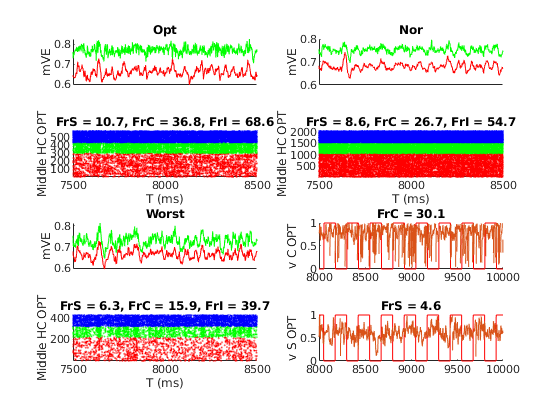

OptE = [L6SFilt>0.93*max(L6S_Drive);  L6CFilt>0.93*max(L6C_Drive)]';
OptI =  L6IFilt'>0.93*max(L6I_Drive);
WorstE = [L6SFilt<1.1*min(L6S_Drive);  L6CFilt<1.1*min(L6C_Drive)]';
WorstI =  L6IFilt'<1.1*min(L6I_Drive);
NorE = OD_E==2 | OD_E==4; NorI = OD_I==2 | OD_I==4;

MidColS = NnS.X>=1*n_S_HC & NnS.X<=2*n_S_HC;
MidRowS = NnS.Y>=1*n_S_HC & NnS.Y<=2*n_S_HC;
MidHCS = MidColS & MidRowS;
MidColC = NnC.X>=1*n_C_HC & NnC.X<=2*n_C_HC;
MidRowC = NnC.Y>=1*n_C_HC & NnC.Y<=2*n_C_HC;
MidHCC = MidColC & MidRowC;
MidHCE = [MidHCS, MidHCC];

MidColI = NnI.X>=1*n_I_HC & NnI.X<=2*n_I_HC;
MidRowI = NnI.Y>=1*n_I_HC & NnI.Y<=2*n_I_HC;
MidHCI= MidColI & MidRowI;

% SOpt = find(OptE & ~EcplxInd);
% scatterSOpt = find(ismember(SpE(:,1), SOpt));
% [~,SOpt_Ind] = ismember(SpE(scatterSOpt,1),scatterSOpt);
% FrSOpt = length(SpE(scatterSOpt,2))/(T/1e3)/length(SOpt);
%
% COpt = find(OptE & EcplxInd);
% scatterCOpt = find(ismember(SpE(:,1), COpt));
% [~,COpt_Ind] = ismember(SpE(scatterCOpt,1),scatterCOpt);
% FrCOpt = length(SpE(scatterCOpt,2))/(T/1e3)/length(COpt);

ShowWin = [7500 8500];
figure('Name','Domain Range')
OD1E = find(OptE & MidHCE);
OD1S = find(OptE & MidHCE & (~EcplxInd));
OD1C = find(OptE & MidHCE & (EcplxInd));
OD1I = find(OptI & MidHCI);
scatter1S = find(ismember(SpE(:,1),OD1S));
scatter1C = find(ismember(SpE(:,1),OD1C));
scatter1I = find(ismember(SpI(:,1),OD1I));
[~,OD1S_Ind] = ismember(SpE(scatter1S,1),OD1S);
[~,OD1C_Ind] = ismember(SpE(scatter1C,1),OD1C);
[~,OD1I_Ind] = ismember(SpI(scatter1I,1),OD1I);
subplot 423
hold on
scatter(SpE(scatter1S,2),OD1S_Ind,0.5,'r.')
scatter(SpE(scatter1C,2),OD1C_Ind+max(OD1S_Ind),0.5,'g.')
scatter(SpI(scatter1I,2),OD1I_Ind+length(OD1E),0.5,'b.');
FrS1 = length(SpE(scatter1S,2))/(T/1e3)/length(OD1S);
FrC1 = length(SpE(scatter1C,2))/(T/1e3)/length(OD1C);
FrI1 = length(SpI(scatter1I,2))/(T/1e3)/length(OD1I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS1,FrC1,FrI1))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 421
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD1S,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD1C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

OD2E = find(NorE & MidHCE);
OD2S = find(NorE & MidHCE & (~EcplxInd));
OD2C = find(NorE & MidHCE & (EcplxInd));
OD2I = find(NorI & MidHCI);
scatter2S = find(ismember(SpE(:,1),OD2S));
scatter2C = find(ismember(SpE(:,1),OD2C));
scatter2I = find(ismember(SpI(:,1),OD2I));
[~,OD2S_Ind] = ismember(SpE(scatter2S,1),OD2S);
[~,OD2C_Ind] = ismember(SpE(scatter2C,1),OD2C);
[~,OD2I_Ind] = ismember(SpI(scatter2I,1),OD2I);
subplot 424
hold on
scatter(SpE(scatter2S,2),OD2S_Ind,0.5,'r.')
scatter(SpE(scatter2C,2),OD2C_Ind+max(OD2S_Ind),0.5,'g.')
scatter(SpI(scatter2I,2),OD2I_Ind+length(OD2E),0.5,'b.');
FrS2 = length(SpE(scatter2S,2))/(T/1e3)/length(OD2S);
FrC2 = length(SpE(scatter2C,2))/(T/1e3)/length(OD2C);
FrI2 = length(SpI(scatter2I,2))/(T/1e3)/length(OD2I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS2,FrC2,FrI2))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 422
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD2E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD2C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Nor')
xlim(ShowWin)

OD3E = find(WorstE & MidHCE);
OD3S = find(WorstE & MidHCE & (~EcplxInd));
OD3C = find(WorstE & MidHCE & (EcplxInd));
OD3I = find(WorstI & MidHCI);
scatter3S = find(ismember(SpE(:,1),OD3S));
scatter3C = find(ismember(SpE(:,1),OD3C));
scatter3I = find(ismember(SpI(:,1),OD3I));
[~,OD3S_Ind] = ismember(SpE(scatter3S,1),OD3S);
[~,OD3C_Ind] = ismember(SpE(scatter3C,1),OD3C);
[~,OD3I_Ind] = ismember(SpI(scatter3I,1),OD3I);
subplot 427
hold on
scatter(SpE(scatter3S,2),OD3S_Ind,0.5,'r.')
scatter(SpE(scatter3C,2),OD3C_Ind+max(OD3S_Ind),0.5,'g.')
scatter(SpI(scatter3I,2),OD3I_Ind+length(OD3E),0.5,'b.');
FrS3 = length(SpE(scatter3S,2))/(T/1e3)/length(OD3S);
FrC3 = length(SpE(scatter3C,2))/(T/1e3)/length(OD3C);
FrI3 = length(SpI(scatter3I,2))/(T/1e3)/length(OD3I);
title(sprintf('FrS = %.1f, FrC = %.1f, FrI = %.1f',FrS3,FrC3,FrI3))
xlabel('T (ms)'); ylabel('Middle HC OPT')
axis tight
xlim(ShowWin)
subplot 425
hold on
plot(StatWin(1:WinNum),nanmean(mVE(OD3E,:)),'r')
plot(StatWin(1:WinNum),nanmean(mVE(OD3C,:)),'g')
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

% subplot 427
% hist(SpE(ismember(SpE(:,1),find(NorE & MidHCE)),2),0:1:T)
% xlabel('T (ms)'); ylabel('Spike count for all E cells')
% axis tight
% xlim(ShowWin)
% subplot 425
% plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
% ylabel('mVE')
% set(gca,'xtick','')
% xlim(ShowWin)
tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
subplot 426
hold on
NeuInd = OD1C(5);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E1 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrC = %.1f',Fr1E1))
ylabel('v C OPT')
subplot 428
hold on
NeuInd = OD1S(1);
OnOff = double(~logical(floor(mod(PhaseE(NeuInd,:) + tCorrect,tMod)/MaxOnPhase)));
plot(StatWin,OnOff,'r')
plot(StatWin(1:WinNum),mVE(NeuInd,:))
xlim([8e3 10e3])
Fr1E2 = length(SpE(ismember(SpE(:,1),NeuInd),2))/(T/1e3)/1;
title(sprintf('FrS = %.1f',Fr1E2))
ylabel('v S OPT')

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);

### Plot Spatial maps: Plot

WinSize = 9000;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));


Determine On and Off t for Frs and mVs: 

Note, we get rid of the first 10ms of each interval

tCorrect = linspace(-T,0,WinNum+1); % Use mV recording time grid
PhaseExc = 20;
mVPh = mod(repmat(PhaseE, 1, WinNum) + repmat(tCorrect(1:end-1), N_E, 1), tMod);
OnOffmV = ~logical(floor(mVPh/MaxOnPhase)); % 1 for all on period, 0 for all off
OnmV  =  OnOffmV & ~(0< mVPh & mVPh<PhaseExc);
OffmV = ~OnOffmV & ~(MaxOnPhase< mVPh & mVPh<MaxOnPhase+PhaseExc);

SpPh = mod(PhaseE(SpE(:,1)) - T + SpE(:,2),tMod);
OnOffSpE =  ~logical(floor(SpPh/MaxOnPhase));
% OnSpE  =  OnOffSpE & ~(0<SpPh & SpPh<PhaseExc);
% OffSpE = ~OnOffSpE & ~(MaxOnPhase<SpPh & SpPh<MaxOnPhase+PhaseExc);
% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

% NnS.X = NnE.X(~EcplxInd); NnS.Y = NnE.Y(~EcplxInd);
% NnC.X = NnE.X(EcplxInd); NnC.Y = NnE.Y(EcplxInd);

FrERan = [0 55];
mVERan = [0.62 0.80];

Figure for ONOFF

First create an onoff vec for each spike

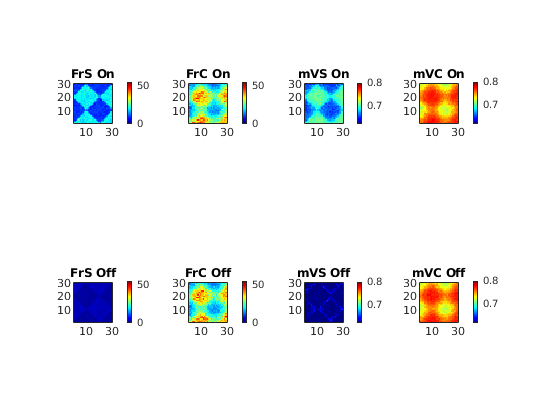

hFrVOnOff = figure('Name','Field_f&V');
% Firing rates:S
subplot 241
ESPinWinOn = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & OnOffSpE;
SpEGoodOn = SpE(ESPinWinOn,1);
[SpCNOn, SpCIOn] = groupcounts(SpEGoodOn);
FrEOn_temp = zeros(N_E,1);
FrEOn_temp(SpCIOn) = SpCNOn*1e3/(EffSize/2);
[FrSOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOnPixMat); title('FrS On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 245
ESPinWinOff = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2) & ~OnOffSpE;
SpEGoodOff = SpE(ESPinWinOff,1);
[SpCNOff, SpCIOff] = groupcounts(SpEGoodOff);
FrEOff_temp = zeros(N_E,1);
FrEOff_temp(SpCIOff) = SpCNOff*1e3/(EffSize/2);
[FrSOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSOffPixMat); title('FrS Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

% Firing rates: C
subplot 242
[FrCOnPixMat,~] = NeuVec2Pixel(FrEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOnPixMat); title('FrC On')
set(gca,'YDir','normal')
axis square
colormap jet; caxis(FrERan)
colorbar

subplot 246
[FrCOffPixMat,~] = NeuVec2Pixel(FrEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCOffPixMat); title('FrC Off')
set(gca,'YDir','normal')
axis square
colormap jet ; caxis(FrERan)
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
% mVs: S
OnmVPhase = double(OnmV);
OnmVPhase(~OnmV) = nan;
mVEOn = mVE; mVEOn = mVEOn.*OnmVPhase;
mVEOn_temp = nanmean(mVEOn(:,SmallWinRange),2);

subplot 243
[mVSOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOnPixMat); title('mVS On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

OffmVPhase = double(OffmV);
OffmVPhase(~OffmV) = nan;
mVEOff = mVE; mVEOff = mVEOff.*OffmVPhase;
mVEOff_temp = nanmean(mVEOff(:,SmallWinRange),2);

subplot 247
[mVSOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(mVSOffPixMat); title('mVS Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

% mVs: C
subplot 244
[mVCOnPixMat,~] = NeuVec2Pixel(mVEOn_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOnPixMat); title('mVC On')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

subplot 248
[mVCOffPixMat,~] = NeuVec2Pixel(mVEOff_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(mVCOffPixMat); title('mVC Off')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; caxis(mVERan)

Figure for All Average

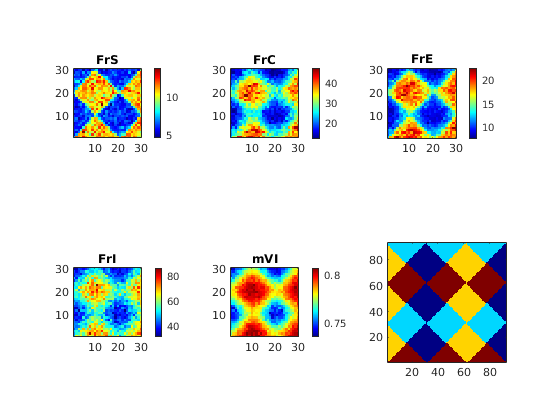

hFrVAll = figure('Name','Field_f&V');
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
%FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

subplot 231
[FrSPixMat,NnSPixel] = NeuVec2Pixel(FrE_temp(~EcplxInd),NnS,NPixX*N_HC,NPixY*N_HC);
imagesc(FrSPixMat); title('FrS')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar
subplot 232
[FrCPixMat,NnCPixel] = NeuVec2Pixel(FrE_temp(EcplxInd),NnC,NPixX*N_HC,NPixY*N_HC);
imagesc(FrCPixMat); title('FrC')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(FrSPixMat*(1-CplxR)+ FrCPixMat*CplxR);
title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

% Orientation domain
% subplot 233
% imagesc(OD_EMap);axis square
% set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

Complex % Simple spikes

% end of 500ms plot
OPTC = find(OD_E == 1 & EcplxInd);
OPTS = find(OD_E == 1 & ~EcplxInd);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
hSpCount = figure('Name','SpCountE')

hSpCount =   Figure (37: SpCountE) with properties:

      Number: 37
        Name: 'SpCountE'
       Color: [0.9400 0.9400 0.9400]
    Position: [1761 1399 560 420]
       Units: 'pixels'

  Show all properties


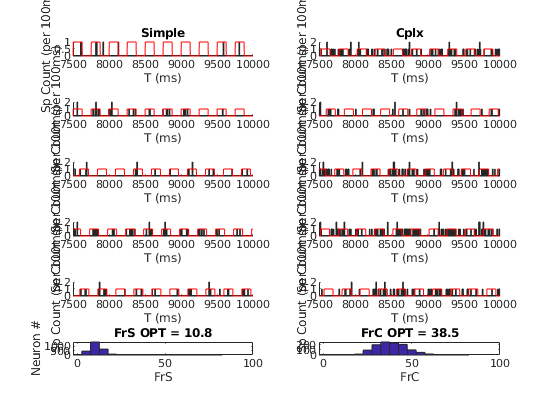

USE = [1,50,300,1000 1500];
for subInd = 1:5
    subplot(6,2,2*subInd-1)
    NeuInd = OPTS(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    if subInd ==1
        title('Simple')
    end

    subplot(6,2,2*subInd)
    NeuInd = OPTC(USE(subInd));
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:10:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd) + tCorrect(1:end-1),tMod)/MaxOnPhase)));
    plot(StatWin(1:WinNum),OnOff,'r')
    xlim([T-T/LGNFreq T])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')

    if subInd ==1
        title('Cplx')
    end

end
OPTS = OptE & ~EcplxInd;
OPTC = OptE & EcplxInd;
subplot(6,2,11)
hist(FrE_temp(OPTS),0:5:80)
title(sprintf('FrS OPT = %.1f', mean(FrE_temp(OPTS))))
xlabel('FrS'); ylabel('Neuron #')
subplot(6,2,12)
hist(FrE_temp(OPTC),0:5:80)
title(sprintf('FrC OPT = %.1f', mean(FrE_temp(OPTC))))
xlabel('FrC')

%save('DriveWkSp.mat')

### A5. MF linear equation for pixels: 1 Matrices

clear ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood...
    mVE mVEOff mVEOn mVI

load(['ConnPixel_Cconst.mat'])
% Present connectivity mats
figure
subplot 221
imagesc(C_SS_Pixel_Us)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_CS_Pixel_Us)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_CI_Pixel_Us)
axis square
colorbar
title('std/mean')

PixNum = NPixX*N_HC * NPixY*N_HC;
FrSPixVec    = reshape(FrSPixMat,  PixNum,1);
FrSOnPixVec  = reshape(FrSOnPixMat,PixNum,1);
FrSOffPixVec = reshape(FrSOffPixMat,PixNum,1);
FrCPixVec    = reshape(FrCPixMat,  PixNum,1);
FrCOnPixVec  = reshape(FrCOnPixMat,PixNum,1);
FrCOffPixVec = reshape(FrCOffPixMat,PixNum,1);
FrIPixVec    = reshape(FrIPixMat,  PixNum,1);

mVSOnPixVec  = reshape(mVSOnPixMat,PixNum,1);
mVSOffPixVec = reshape(mVSOffPixMat,PixNum,1);
mVCOnPixVec  = reshape(mVCOnPixMat,PixNum,1);
mVCOffPixVec = reshape(mVCOffPixMat,PixNum,1);
mVIPixVec = reshape(mVIPixMat,PixNum,1);

% Precompute LGN and L6
lambda_SOn_Pixel = zeros(PixNum,1);
lambda_SOff_Pixel = zeros(PixNum,1);
lambda_COn_Pixel = zeros(PixNum,1);
lambda_COff_Pixel = zeros(PixNum,1);
L6S_Pixel = zeros(PixNum,1);
L6C_Pixel = zeros(PixNum,1);
L6I_Pixel = zeros(PixNum,1);
lambda_SOn_drive = lambda_EOn_drive(~EcplxInd); lambda_COn_drive = lambda_EOn_drive(EcplxInd);
lambda_SOff_drive = lambda_EOff_drive(~EcplxInd); lambda_COff_drive = lambda_EOff_drive(EcplxInd);
rS_L6_Drive = rE_L6_Drive(~EcplxInd); rC_L6_Drive = rE_L6_Drive(EcplxInd);
for PixInd = 1:PixNum
    lambda_SOn_Pixel(PixInd)  = mean(lambda_SOn_drive(NnSPixel.Vec == PixInd));
    lambda_SOff_Pixel(PixInd) = mean(lambda_SOff_drive(NnSPixel.Vec == PixInd));
    lambda_COn_Pixel(PixInd)  = mean(lambda_COn_drive(NnCPixel.Vec == PixInd));
    lambda_COff_Pixel(PixInd) = mean(lambda_COff_drive(NnCPixel.Vec == PixInd));
    L6S_Pixel(PixInd) = mean(rS_L6_Drive(NnSPixel.Vec == PixInd));
    L6C_Pixel(PixInd) = mean(rC_L6_Drive(NnCPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive_Pre;

Below need work

% Setup preused Firing rates for off E
%FrPreUseDim = find(lambda_EOff_Pixel<0.08) + PixNum;
FrPreUseDim = (1:PixNum) + 2*PixNum;
FrPreUse = FrSOffPixVec(FrPreUseDim - 2*PixNum);
%FrPreUse = FrEOffLIF(FrPreUseDim - PixNum);
FrPreUse = [];

### A6. Clear redundant variables for memory

clear C_EE C_EE_Fix_Bd C_EI C_EI_Fix_Bd...
    C_IE C_IE_Fix_Bd C_II C_II_Fix_Bd...
    C_SS_Fix_Bd C_SC_Fix_Bd C_CS_Fix_Bd C_CC_Fix_Bd...
    C_SI_Fix_Bd C_CI_Fix_Bd C_IS_Fix_Bd C_IC_Fix_Bd...
    COpt_Ind SOpt_Ind scatterCOpt scatterSOpt...
    ESPinWin ESPinWinOn ESPinWinOff ISPinWin...
    OffmVPhase OnmVPhase OnOffmV OnOffSpE OnmV OffmV...
    SpE SpECurrent SpEGood SpEGoodOff SpEGoodOn SpI SpICurrent SpIGood SpPh...
    mVE mVEOff mVEOn mVI ...
    NWTrace AmbE_Events AdjlgnE AmbI_Events CMatAll ...
    EampaInp EnmdaInp GE_ETemp GE_ITemp IampaInp InmdaInp ...
    L6E_Events L6I_Events lgnE_Events lgnI_Events...
    mVECurrent mVICurrent mVETemp mVPh
save([SaveFolder,'AllMFPixPara_Paper2TuneFig1V4D2.mat'])